clear
close all
%% 0. Initialize Parameters 
n = 1250;                  % Number of locations to evaluate bridge failure 
L = 1250;                  % Length of bridge 
  
x = linspace(0, L, n);     % Define x coordinate 


pointLoad_Locations = [550,1250];
pointLoad = [185,185];


[sfdGraph , bmdGraph] = PointLoads(pointLoad_Locations, pointLoad,L);

%[maxMoment,minMoment] = trainData(L)

%% 2. Define cross-sections for design 0
height = 75; % side flang
thik = 1.27;
tf = 100;
bf = 80;
stickPart = 10;
a = [550,550,510,510,190,190]; %Largest Distance
a_x = [0,549,550,1059,1060,1250];

%% 3. Define Material Properties 
SigT = 30; 
SigC = 6; 
E    = 4000;
TauU = 4; 
TauG = 2; 
mu   = 0.2; 

[ybar_x,I_x,Q_x,QGlue_x,ytop,ybot] = SectionProperties(thik,tf,height,bf,stickPart,n);
V_Mat = Vfail(I_x,Q_x,TauU,thik);
V_Glue = VfailGlue(I_x,QGlue_x,TauG);
V_Buck = VfailBuck(I_x,Q_x,thik, height, E, mu,a,a_x,x);
  
M_MatT = MfailMatT(bmdGraph,I_x, ybot, ytop,SigT,x);
M_MatC = MfailMatC(bmdGraph,I_x, ybot, ytop,SigC,x);
M_Buck1 = MfailBuck1(bmdGraph,I_x,thik, E, mu, ytop,ybot,bf,x);
M_Buck2 = MfailBuck2(bmdGraph,I_x,thik, E, mu, ytop,ybot,bf,x,tf);
M_Buck3 = MfailBuck3(bmdGraph,I_x,thik, E, mu, ytop,ybot,x); 

[ Pf ] = FailLoad(pointLoad(1), sfdGraph, bmdGraph, V_Mat,V_Glue, V_Buck, M_MatT, M_MatC,M_Buck1,M_Buck2,M_Buck3)

Pf = 207.7088

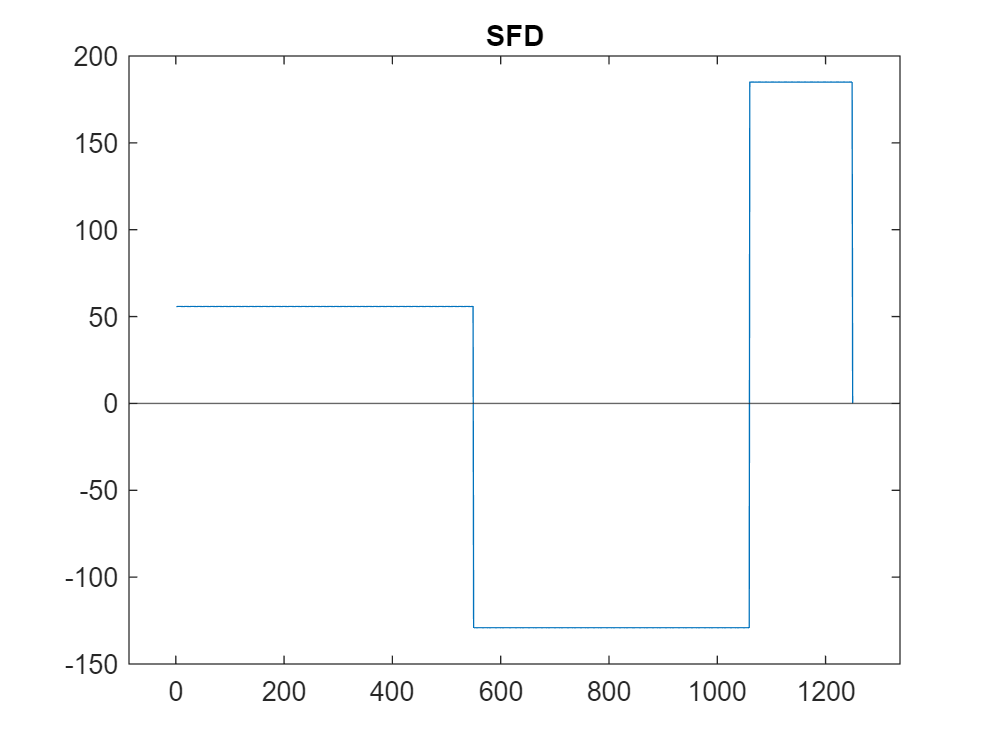


plot(1:L,sfdGraph)
axis padded
yline(0,'-')
title("SFD")

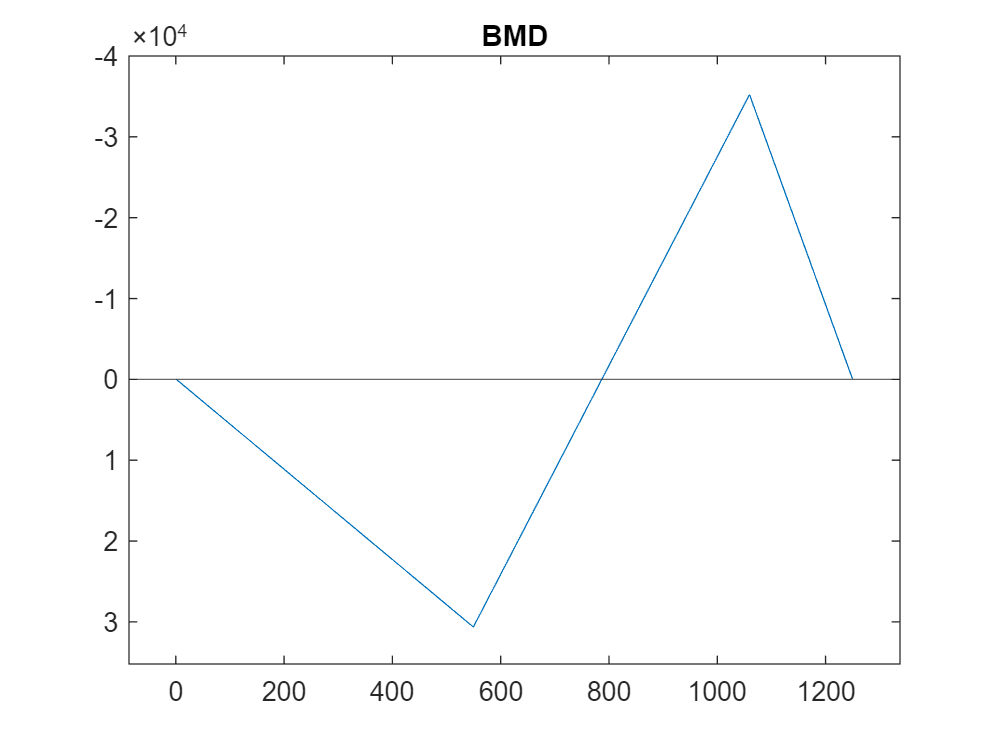


plot(1:L,bmdGraph)
set(gca, 'YDir','reverse')
axis padded
yline(0,'-')
title("BMD")

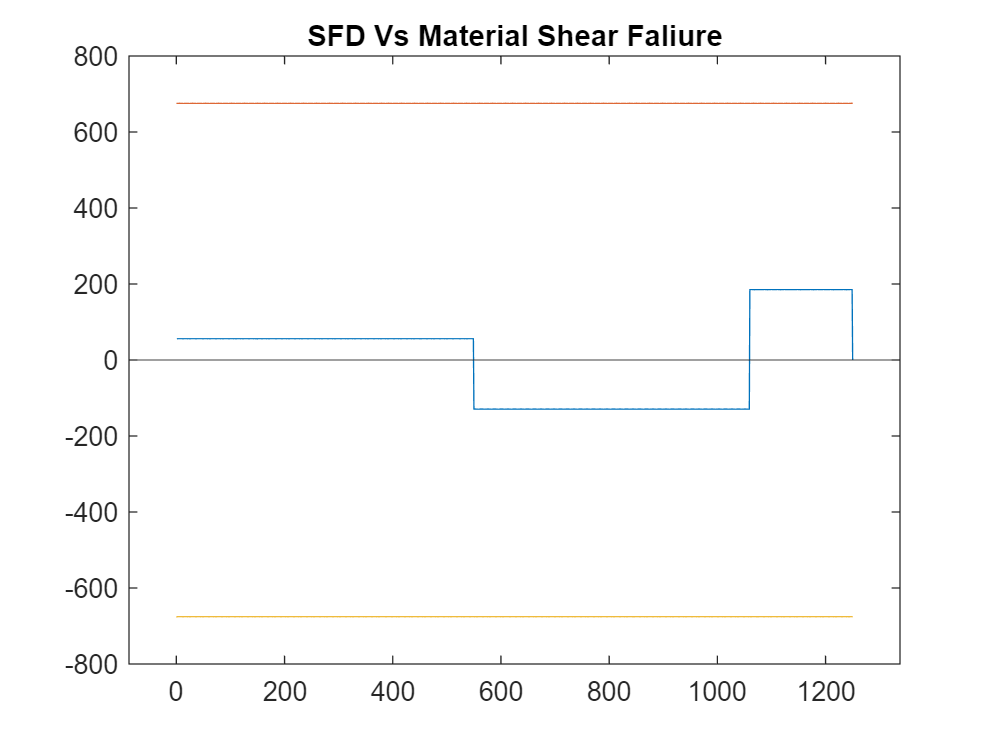


plot(1:L,sfdGraph)
hold on
plot(x,V_Mat)
plot(x,-V_Mat)
axis padded
yline(0,'-')
title("SFD Vs Material Shear Faliure")

hold off

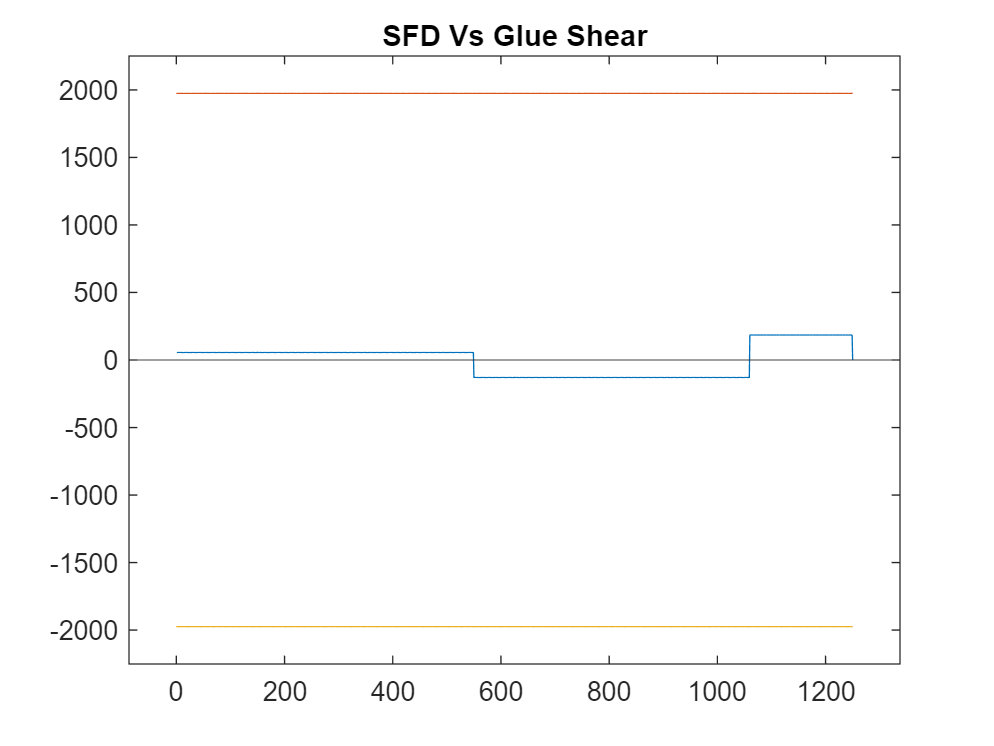

plot(1:L,sfdGraph)
hold on
plot(x,V_Glue)
plot(x,-V_Glue)
axis padded
yline(0,'-')
title("SFD Vs Glue Shear")

hold off

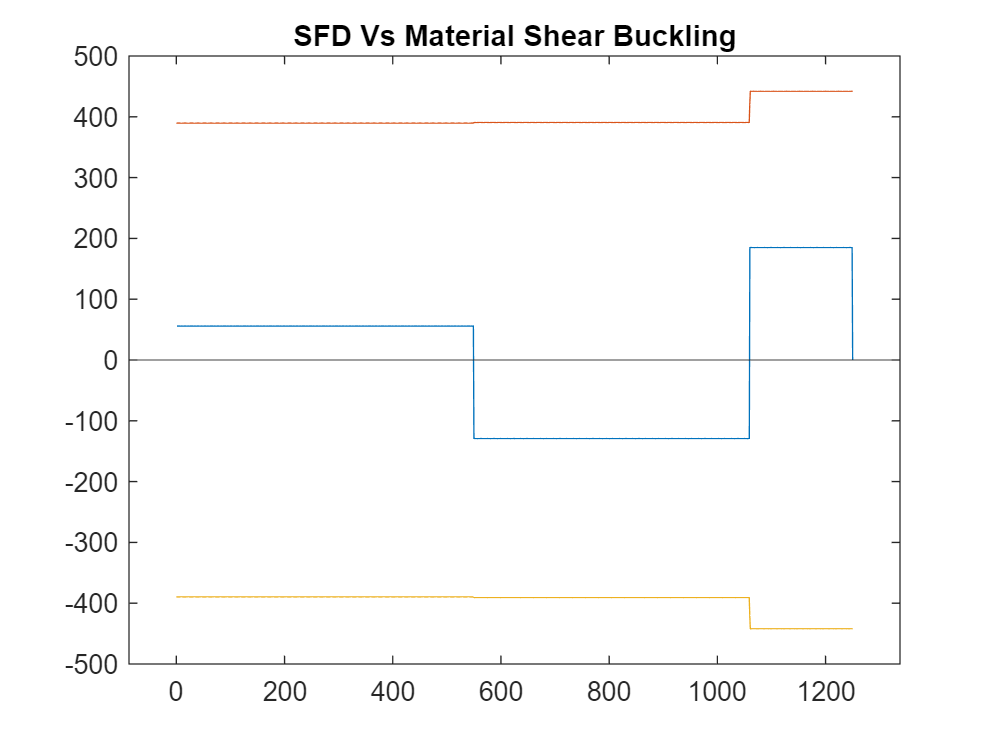

plot(1:L,sfdGraph)
hold on
plot(x,V_Buck)
plot(x,-V_Buck)
axis padded
yline(0,'-')
title("SFD Vs Material Shear Buckling")

hold off

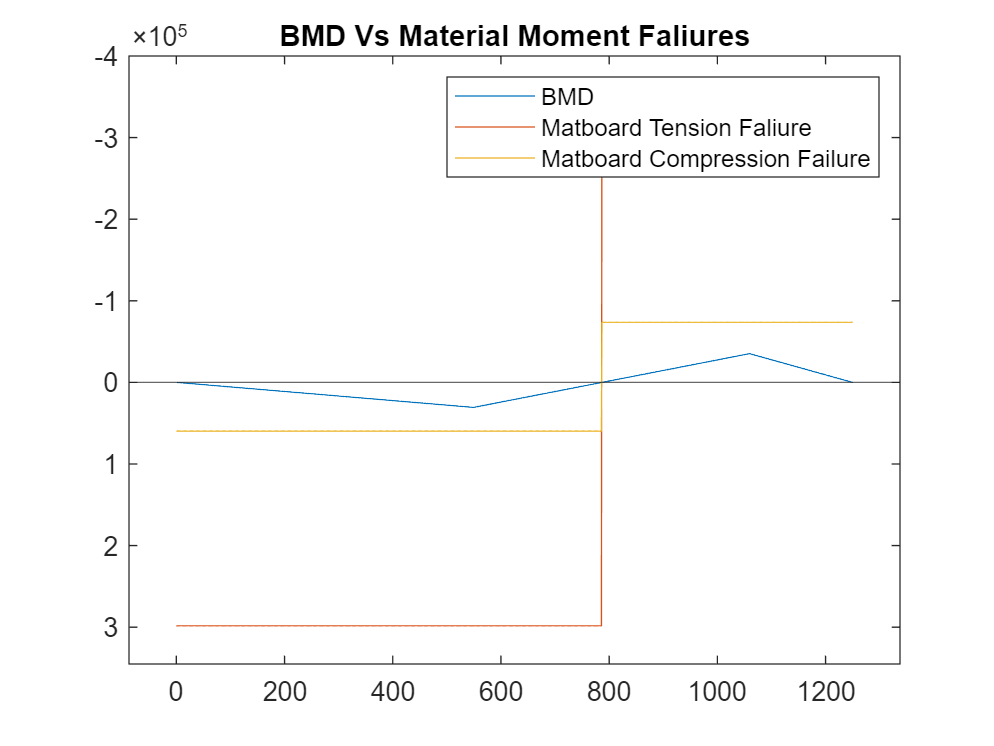

plot(1:L,bmdGraph)
hold on
plot(x,M_MatT)
plot(x,M_MatC)
axis padded
yline(0,'-')
set(gca, 'YDir','reverse')
title("BMD Vs Material Moment Faliures")
legend(["BMD","Matboard Tension Faliure","Matboard Compression Failure"])

hold off

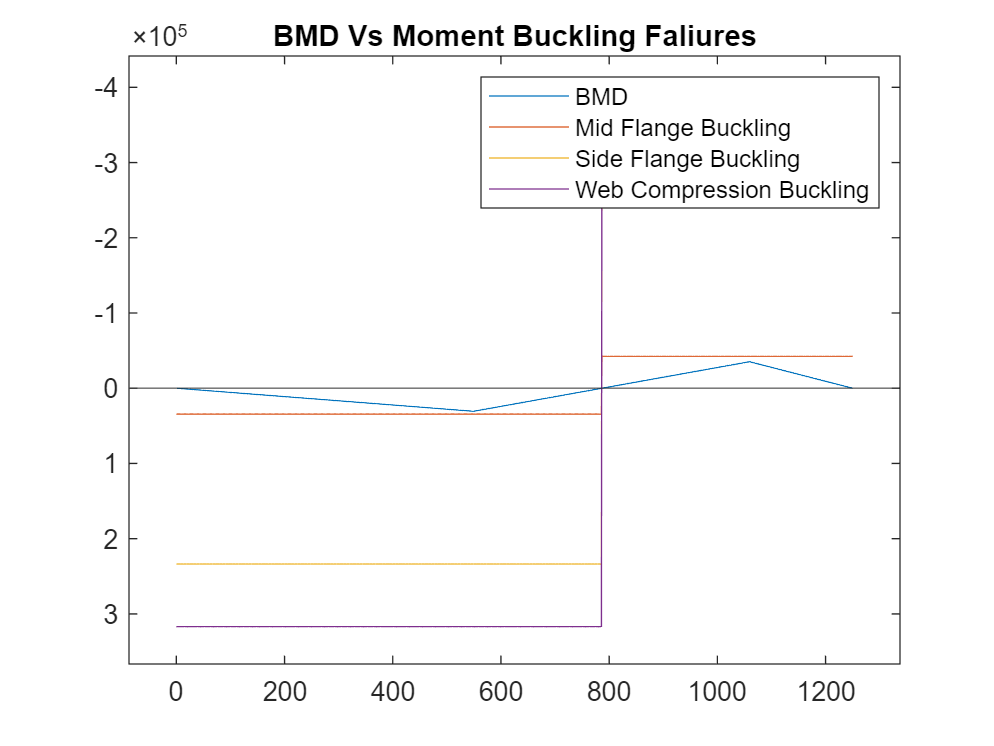

plot(1:L,bmdGraph)
hold on
plot(x,M_Buck1)
plot(x,M_Buck2)
plot(x,M_Buck3)%%%%%%%%%%%%%%%%%%%%%%%%Figure out b in the function
axis padded
yline(0,'-')
set(gca, 'YDir','reverse')
title("BMD Vs Moment Buckling Faliures")
legend(["BMD","Mid Flange Buckling","Side Flange Buckling","Web Compression Buckling"])

function[maxMoment,minMoment] = trainData(L)
    pointLoad = [66.7 66.7 66.7 66.7 66.7 66.7];
    maxMoment = -10000000*ones(1,L);
    minMoment = 100000000*ones(1,L);
    for i = linspace(0,L,40)
        pointLoad_Locations = [0,176,340,516,680,856]+i;
        [sfd,bmd] =PointLoads(pointLoad_Locations, pointLoad,L);
        
        maxMoment = max(maxMoment, bmd);
        minMoment = min(minMoment,bmd);

        figure(1)
        plot(1:L,sfd)
        axis padded
        yline(0,'-')
        title("SFD Train")

        hold on
        
        figure(2)
        plot(1:L,bmd)
        set(gca, 'YDir','reverse')
        axis padded
        yline(0,'-')
        title("BMD Train")

        hold on
    end
end

function [sfdGraph , bmdGraph] = PointLoads(pointLoad_Locations,pointLoad,L)
reactionBDisToA = 1060;

for i = 1:length(pointLoad_Locations)
    if pointLoad_Locations(i) > L
        pointLoad(i) = 0;
    end
end

By = sum(pointLoad_Locations .* pointLoad)/reactionBDisToA;
Ay = sum(pointLoad)-By;


sfdPointLoads = [Ay, ...
                -pointLoad(pointLoad_Locations <= reactionBDisToA), ...
                By, ...
                -pointLoad(pointLoad_Locations > reactionBDisToA)];%I made point loads negative

sfdPointLocations = [0, ...
                    pointLoad_Locations(pointLoad_Locations <= reactionBDisToA), ...
                    reactionBDisToA, ...
                    pointLoad_Locations(pointLoad_Locations > reactionBDisToA)];

sfd = cumsum(sfdPointLoads);


sfdGraph = zeros(L,1);
for i=1:L
    sfdGraph(i) = sfd(find(sfdPointLocations <= i, 1, 'last'));
end

bmdGraph = cumtrapz(sfdGraph);
end


function [ybar_x,I_x,Q_x,QGlue_x,ytop,ybot] = SectionProperties(thik,tf,height,bf,stickPart,n)
Areas = zeros(6,1);
ydistance = zeros(6,1);
IValues = zeros(6,1);
dValues = zeros(6,1);
% Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% Input: Geometric Inputs. Format will depend on user 
% Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
Areas(1) = tf * thik;
ydistance(1) = height - (thik/2);

Areas(2) = bf * thik;
ydistance(2) = (thik/2);

Areas(3) =  (height + (thik*-3)) * thik;
ydistance(3) = ((0.5*((height + (thik*-3))))+ thik);

Areas(4) = (height + (thik*-3)) * thik;
ydistance(4) = ((0.5*((height + (thik*-3))))+ thik);

Areas(5) = (stickPart * thik);
ydistance(5) = height - thik - (thik/2);

Areas(6) = (stickPart * thik);
ydistance(6) = height - thik - (thik/2);

ybarTop = 0;
ybarBot = 0;

for i = 1:6
    ybarTop = ybarTop + Areas(i)*ydistance(i);
    ybarBot = ybarBot + Areas(i);
end

ybar = ybarTop/ybarBot;
ybar_x = ybar * ones(1,n);

IValues(1) = (tf * thik^3)/12;
IValues(2) = (bf * thik^3)/12;
IValues(3) = (thik * (height-(thik*3))^3)/12;
IValues(4) = (thik * (height-(thik*3))^3)/12;
IValues(5) = (stickPart * thik^3)/12;
IValues(6) = (stickPart * thik^3)/12;

dValues(1) = height - ybar - (thik/2);
dValues(2) = ybar - (thik/2);
dValues(3) = ybar - (((height - thik*3)/2)+thik);
dValues(4) = ybar - (((height - thik*3)/2)+thik);
dValues(5) = (height - thik - (thik/2)) - ybar;
dValues(6) = (height - thik - (thik/2)) - ybar;

I = 0;
for i = 1:6
    I = I + IValues(i) + Areas(i)*(dValues(i))^2;
end
I_x = I .* ones(1,n);

Q = (Areas(2)*dValues(2)) + ((ybar - thik) * thik)*(ybar - thik)/2 *2;
Q_x = Q .* ones(1,n);

QGlue = Areas(1)*dValues(1);
QGlue_x = QGlue .* ones(1,n);

ytop = (height - ybar_x) .* ones(1,n);
ybot = (ybar_x) .* ones(1,n);
end


function [ V_fail ] = Vfail(I_x,Q_x,TauU,thik) 
% Calculates shear forces at every value of x that would cause a matboard shear failure 
% Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% Output: V_fail a 1-D array of length n  
    b = thik * 2; %%%%Change for diffrent cross section
 
    V_fail = TauU .* I_x .* b ./ Q_x;  
end 

function [ V_Glue ] = VfailGlue(I_x,QGlue_x,TauG)
    b = 10; %Glue Area Design0 %%%%Change for diffrent cross section
 
    V_Glue = TauG .* I_x .* b ./ QGlue_x;  
end

function [V_Buck] = VfailBuck(I_x,Q_x,thik, height, E, mu,a,a_x,x)
    b = thik;
    a_s = interp1(a_x,a,x);
    TauBuck = ((5*pi^2*E)/12*(1-mu^2)) .* ((thik./a_s).^2 + (thik/height)^2);
    V_Buck = TauBuck .* I_x .* b ./ Q_x;
end

function [M_MatT] = MfailMatT(bmdGraph,I_x, ybot, ytop,SigT,x)
% Calculates bending moments at every value of x that would cause a matboard tension failure 
% Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% Output: M_MatT a 1-D array of length n 
for i = 1 : length(x) 
    if bmdGraph(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
        M_MatT(i) = SigT * I_x(i) / ybot(i); 
    elseif bmdGraph(i) < 0 % If the moment is negative, the tension failure will be at the top 
         M_MatT(i) = -SigT * I_x(i) / ytop(i); 
    end 
    end 
end 

function [M_MatC] = MfailMatC(bmdGraph,I_x, ybot, ytop,SigC,x)
for i = 1 : length(x) 
    if bmdGraph(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
        M_MatC(i) = SigC * I_x(i) / ybot(i); 
    elseif bmdGraph(i) < 0 % If the moment is negative, the tension failure will be at the top 
         M_MatC(i) = -SigC * I_x(i) / ytop(i); 
    end 
    end 
end

function M_Buck1 = MfailBuck1(bmdGraph,I_x,thik, E, mu, ytop,ybot,bf,x)
    b = bf;
    stressBuck1 = ((4*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if bmdGraph(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck1(i) = stressBuck1*I_x(i)/ybot(i);
        elseif bmdGraph(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck1(i) = -stressBuck1*I_x(i)/ytop(i);
        end 
    end 
end

function M_Buck2 = MfailBuck2(bmdGraph,I_x,thik, E, mu, ytop,ybot,bf,x,tf)
    b = (tf-bf)/2;
    stressBuck2 = ((0.425*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if bmdGraph(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck2(i) = stressBuck2*I_x(i)/ybot(i);
        elseif bmdGraph(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck2(i) = -stressBuck2*I_x(i)/ytop(i);
        end 
    end 
end

function M_Buck3 = MfailBuck3(bmdGraph,I_x,thik, E, mu, ytop,ybot,x)
    b = ytop-thik; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% I am not sure what b should be
    stressBuck3 = ((6*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if bmdGraph(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck3(i) = stressBuck3(i)*I_x(i)/ybot(i);
        elseif bmdGraph(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck3(i) = -stressBuck3(i)*I_x(i)/ytop(i);
        end 
    end 
end

function [ Pf ] = FailLoad( P, SFD, BMD, V_Mat,V_Glue, V_Buck, M_MatT, M_MatC,M_Buck1,M_Buck2,M_Buck3)
        FosVMat = min (abs(V_Mat./SFD'));
        FosV_Glue = min (abs(V_Glue./SFD'));
        FosV_Buck = min (abs(V_Buck./SFD'));
        FosM_MatT = min (abs(M_MatT./BMD'));
        FosM_MatC = min (abs(M_MatC./BMD'));
        FosM_Buck1 = min (abs(M_Buck1./BMD'));
        FosM_Buck2 = min (abs(M_Buck2./BMD'));
        FosM_Buck3 = min (abs(M_Buck3./BMD'));

        Pf = min([FosVMat*P,FosV_Glue*P,FosV_Buck*P,FosM_MatT*P,FosM_MatC*P,FosM_Buck1*P,FosM_Buck2*P,FosM_Buck3*P]);
end